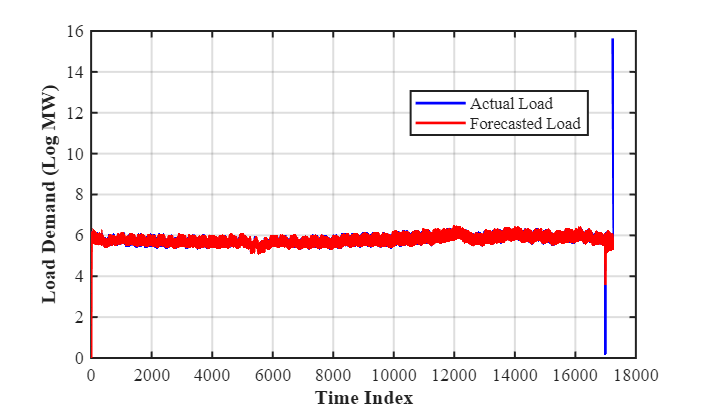

clc; clear; close all;

%% =====================================================
% HWT LOAD FORECASTING MODEL (CONFERENCE PAPER VERSION)
% Includes:
% 1. Actual vs Forecast Plot
% 2. Zoom Plot
% 3. MAPE vs Horizon Plot
% 4. PNG Export (600 DPI)
%% =====================================================

%% =========================
% LOAD DATA
%% =========================
data = readtable('data/Complete_datasheet.csv');

y = double(data.Log_MW);
y = fillmissing(y,'linear');

T = length(y);

%% =========================
% PARAMETERS
%% =========================
m1 = 48;      % Daily seasonality
m2 = 336;     % Weekly seasonality

alpha = 0.20;
delta = 0.10;
omega = 0.05;

%% =========================
% INITIALIZATION
%% =========================
l = zeros(T,1);
d = zeros(T,1);
w = zeros(T,1);
y_pred = zeros(T,1);

l(1) = y(1);

for i = 1:m1
    d(i) = y(i) - l(1);
end

for i = 1:m2
    w(i) = y(i) - l(1);
end

%% =========================
% HWT MODEL TRAINING
%% =========================
for t = max(m1,m2)+1:T
    
    y_pred(t) = l(t-1) + d(t-m1) + w(t-m2);
    
    e = y(t) - y_pred(t);
    
    l(t) = l(t-1) + alpha*e;
    d(t) = d(t-m1) + delta*e;
    w(t) = w(t-m2) + omega*e;
end

valid = max(m1,m2)+1:T;

%% =====================================================
% FIGURE 1 : ACTUAL vs FORECAST
%% =====================================================
figure('Color','w','Position',[100 100 720 420]);

plot(y(valid),'b','LineWidth',1.6); hold on;
plot(y_pred(valid),'r','LineWidth',1.6);

grid on;
box on;

xlabel('Time Index','FontSize',12,'FontWeight','bold');
ylabel('Load Demand (Log MW)','FontSize',12,'FontWeight','bold');

legend({'Actual Load','Forecasted Load'},...
    'Location','best','FontSize',10);

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'HWT_Actual_vs_Forecast.png','Resolution',600);

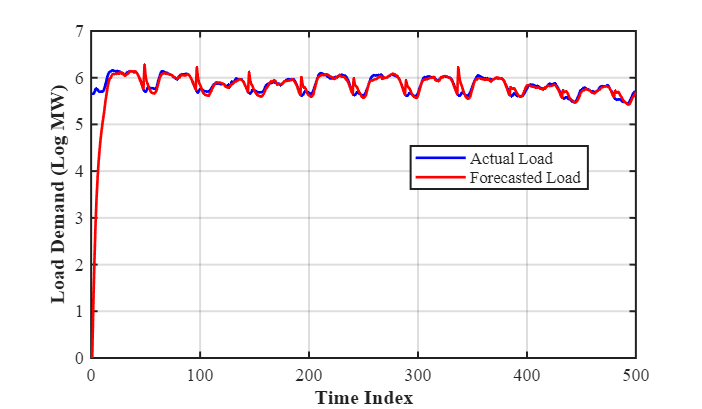


%% =====================================================
% FIGURE 2 : ZOOM VIEW
%% =====================================================
figure('Color','w','Position',[120 120 720 420]);

plot(y(valid(1:500)),'b','LineWidth',1.6); hold on;
plot(y_pred(valid(1:500)),'r','LineWidth',1.6);

grid on;
box on;

xlabel('Time Index','FontSize',12,'FontWeight','bold');
ylabel('Load Demand (Log MW)','FontSize',12,'FontWeight','bold');

legend({'Actual Load','Forecasted Load'},...
    'Location','best','FontSize',10);

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'HWT_Zoom_View.png','Resolution',600);

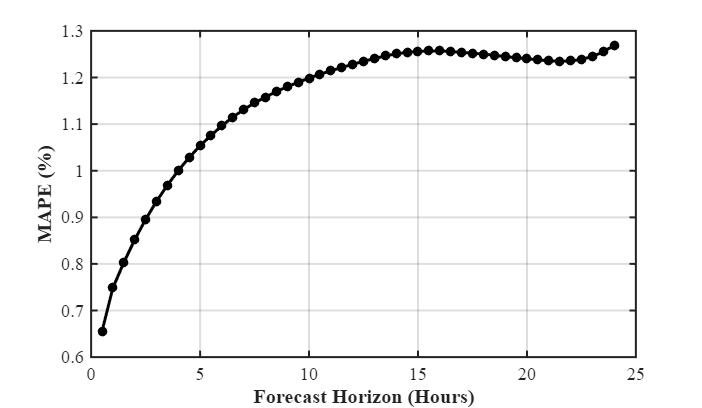


%% =========================
% MAPE vs HORIZON
%% =========================
max_h = 48;
MAPE = zeros(max_h,1);

for h = 1:max_h
    
    err = [];
    
    for t = valid(1):(T-h)
        
        y_hat = l(t) + d(t+h-m1) + w(t+h-m2);
        y_true = y(t+h);
        
        if y_true ~= 0
            err = [err; abs((y_true-y_hat)/y_true)];
        end
    end
    
    MAPE(h) = mean(err)*100;
end

%% =====================================================
% FIGURE 3 : MAPE vs HORIZON
%% =====================================================
figure('Color','w','Position',[140 140 720 420]);

plot((1:max_h)/2,MAPE,'k-o',...
    'LineWidth',1.8,...
    'MarkerSize',4,...
    'MarkerFaceColor','k');

grid on;
box on;

xlabel('Forecast Horizon (Hours)',...
    'FontSize',12,'FontWeight','bold');

ylabel('MAPE (%)',...
    'FontSize',12,'FontWeight','bold');

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'HWT_MAPE_vs_Horizon.png','Resolution',600);


%% =====================================================
% TABLE OUTPUT
%% =====================================================
horizon = (1:max_h)'/2;

MAPE_Table = table(horizon,MAPE,...
    'VariableNames',{'Horizon_Hours','MAPE_percent'});

disp(MAPE_Table);

    Horizon_Hours    MAPE_percent
    _____________    ____________

         0.5           0.65539   
           1           0.74874   
         1.5           0.80302   
           2           0.85194   
         2.5           0.89541   
           3            0.9342   
         3.5           0.96908   
           4            1.0004   
         4.5            1.0284   
           5            1.0536   
         5.5            1.0758   
           6            1.0965   
         6.5             1.115   
           7            1.1313   
         7.5            1.1454   
           8            1.1581   
         8.5            1.1699   
           9            1.1804   
         9.5            1.1899   
          10            1.1988   
        10.5             1.207   
          11            1.2143   
        11.5            1.2215   
          12            1.2283   
        12.5            1.2347   
          13 


writetable(MAPE_Table,'HWT_MAPE_Table.csv');

%% =====================================================
% ERROR METRICS
%% =====================================================
rmse = sqrt(mean((y(valid)-y_pred(valid)).^2));
mae  = mean(abs(y(valid)-y_pred(valid)));

fprintf('\nRMSE = %.4f\n',rmse);


RMSE = 0.1235


fprintf('MAE  = %.4f\n',mae);

MAE  = 0.0237



disp('Saved Files:');

Saved Files:


disp('1. HWT_Actual_vs_Forecast.png');

1. HWT_Actual_vs_Forecast.png


disp('2. HWT_Zoom_View.png');

2. HWT_Zoom_View.png


disp('3. HWT_MAPE_vs_Horizon.png');

3. HWT_MAPE_vs_Horizon.png


disp('4. HWT_MAPE_Table.csv');

4. HWT_MAPE_Table.csv
